## LAB 11 SNS

## SYED SUALEH ABBAS     10303

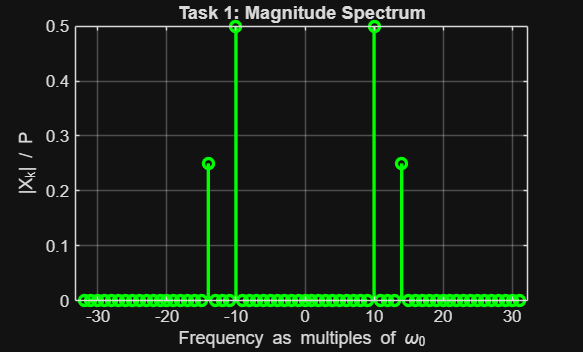

%TASK 1:
P = 64;
w0 = 2*pi/P;
n = 0:P-1;
x = cos(10*w0*n) + 0.5*cos(14*w0*n); % Composite signal

hx = fft(x); % Compute DFT
shx = fftshift(hx); % Shift zero-frequency to center
f_axis = -P/2 : P/2-1; % Symmetric frequency axis

stem(f_axis, abs(shx)/P, 'g', 'LineWidth', 2);
title('Task 1: Magnitude Spectrum');
xlabel('Frequency as multiples of \omega_0');
ylabel('|X_k| / P');
grid on;

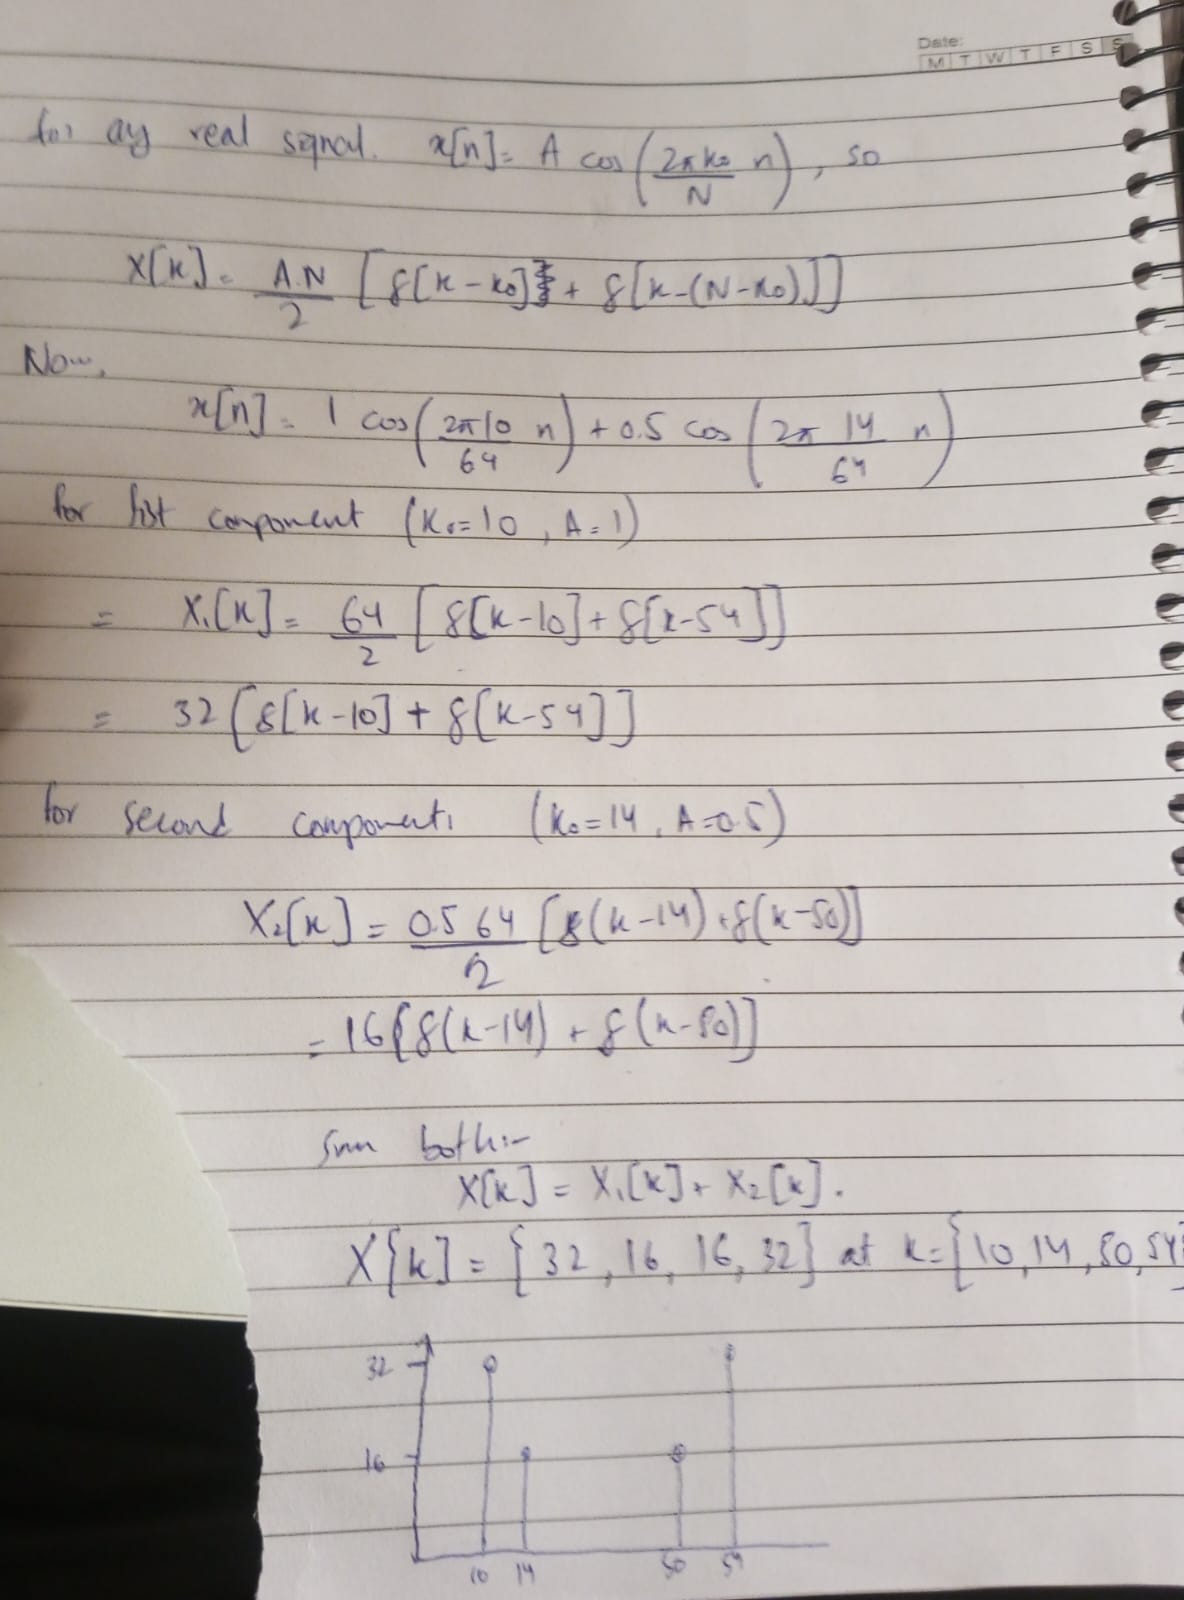

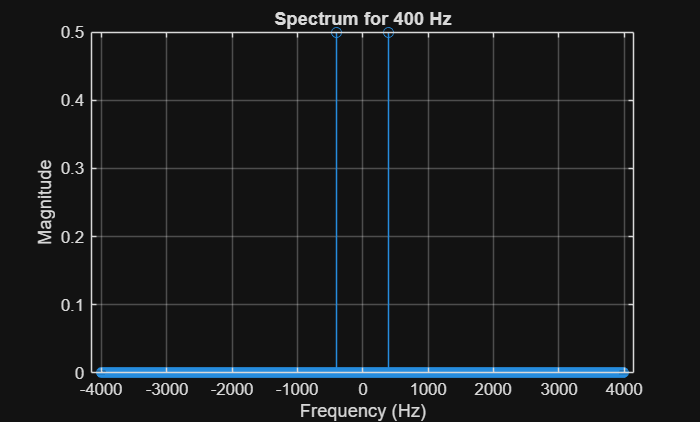

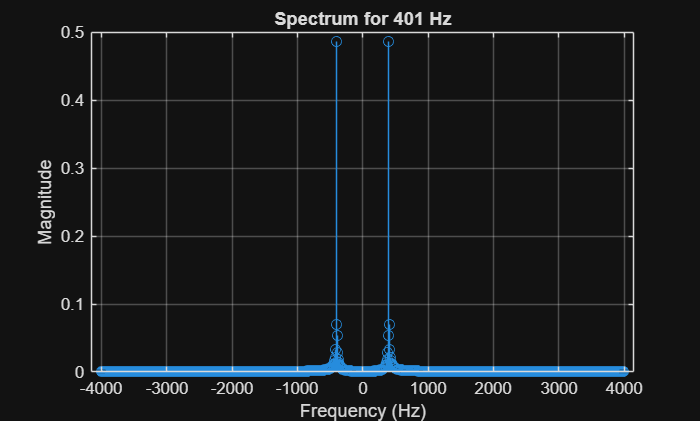

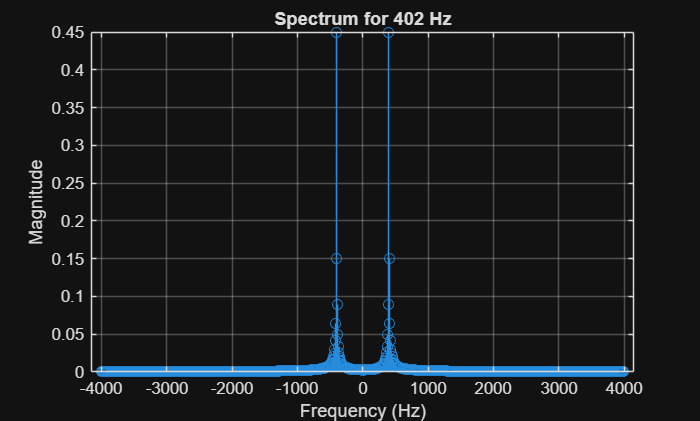

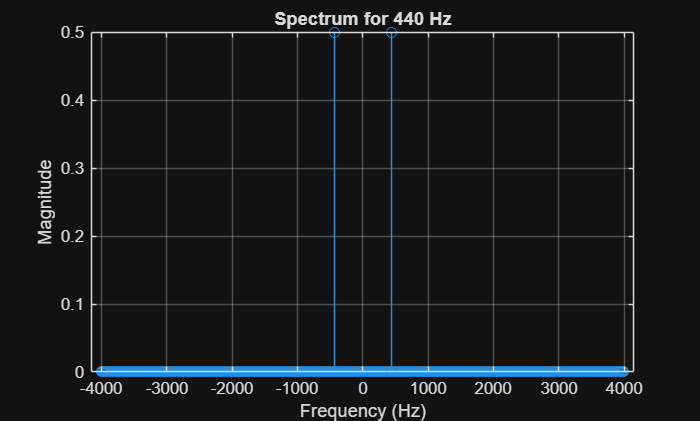

%Task 2:
Fs = 8000;          % Sampling frequency
N = 1000;           % Number of initial samples 
t = (0:N-1)/Fs;     % Time vector
freqs = [400, 401, 402, 440]; 

% Part 1: Testing the 4 frequencies 
for f = freqs
    x = sin(2*pi*f*t);
    
    % Compute FFT and shift it
    hx = fftshift(fft(x, N)); 
    
    % Create frequency axis in Hz 
    fHz = (-N/2 : N/2-1) * (Fs/N); 
    
    figure;
    stem(fHz, abs(hx)/N); % Normalized magnitude
    title(['Spectrum for ', num2str(f), ' Hz']);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
    grid on;
    
end

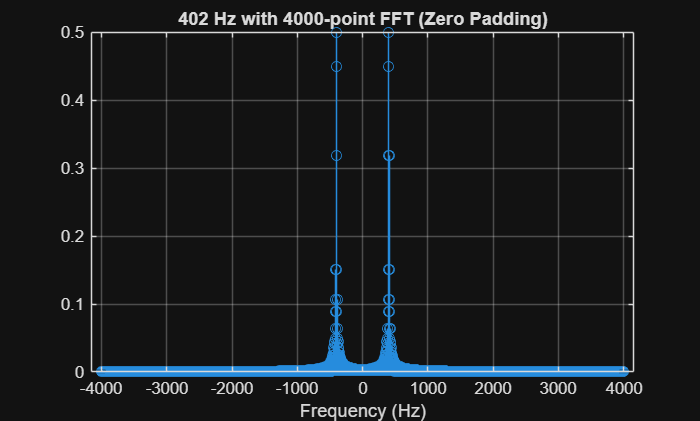

% Part 2: Increase FFT points (Zero Padding)
% Using fft = 4000 but keeping same 1000 samples of x
N_fft = 4000;
x_402 = sin(2*pi*402*t); % still only 1000 samples
hx_pad = fftshift(fft(x_402, N_fft));
fHz_pad = (-N_fft/2 : N_fft/2-1) * (Fs/N_fft);

figure;
stem(fHz_pad, abs(hx_pad)/N); 
title('402 Hz with 4000-point FFT (Zero Padding)');
xlabel('Frequency (Hz)');
grid on;

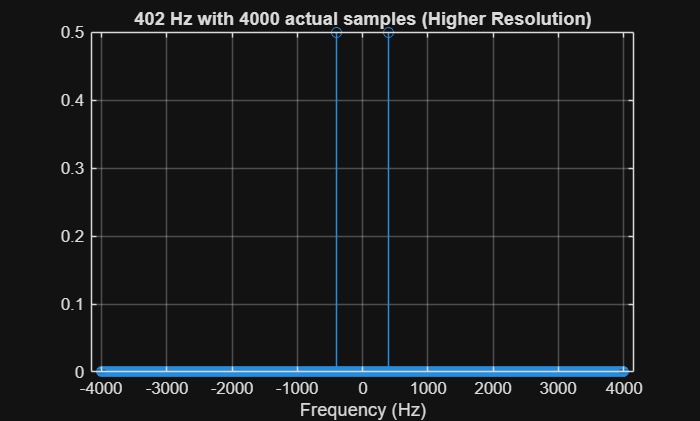

%This just makes the curve look smoother.

% Part 3: Increase actual time samples
N_long = 4000;      % Capture 4000 samples now
t_long = (0:N_long-1)/Fs;
x_long = sin(2*pi*402*t_long); 

hx_long = fftshift(fft(x_long, N_long));
fHz_long = (-N_long/2 : N_long/2-1) * (Fs/N_long);

figure;
stem(fHz_long, abs(hx_long)/N_long);
title('402 Hz with 4000 actual samples (Higher Resolution)');
xlabel('Frequency (Hz)');
grid on;

% This makes the peak much narrower and more accurate.

## What’s special about 400 Hz and 440 Hz?

Note that 400Hz and 440Hz are **integer multiples** of the frequency resolution Delta f = Fs/N = 8000/1000 = 8 Hz.

- 400 / 8 = 50 (Integer)

- 440 / 8 = 55 (Integer)

- Because they are exact multiples, their energy falls exactly into one frequency bin (a clean spike). The frequencies 401 and 402 are not multiples of 8, causing **spectral leakage** (the energy spreads across neighboring bins).

## Increase the number of points in FFT by using fft(x,N) where N is number of points. What effect does it have?

Increasing N while keeping the original 1000 samples is called **Zero-Padding**.

**The Result:** It’s like "digital zooming." It doesn't actually give you new information or better resolution, but it calculates more points in between the original ones. It makes the plot look smoother and less "blocky," but it won't help you separate two frequencies that are very close together.

## Increase the number of samples of in discrete-time signal from 1000 to 4000 in the case of 402Hz. How does that affect the plot?

Watching the signal for a longer time, which makes the frequency resolution much finer (Delta f = 8000/4000 = 2 Hz).

The "leakage" or width of the 402 Hz peak will shrink significantly. The peak becomes much sharper and more accurate because you gave the computer more data to work with.

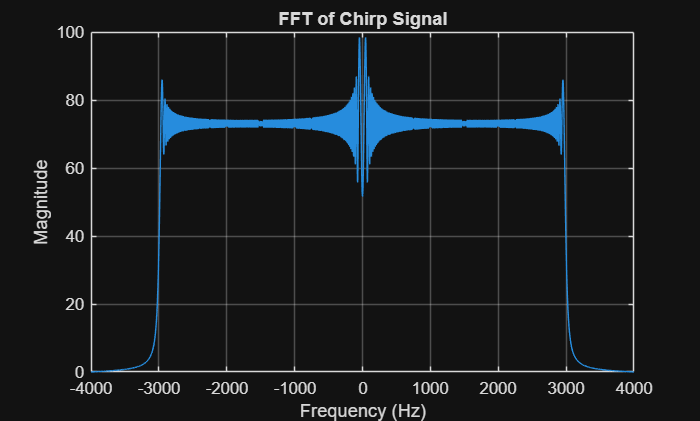

%% Task 3: Chirp Signal Analysis
fs = 8000;              % Sampling frequency
t = (0:7999)/fs;        % Time vector for 8000 samples (1 second)

x = cos(3000 * pi * t.^2); % Quadratic phase creates a linear frequency sweep

% Finding and plot the FFT
hx = fftshift(fft(x));
f_axis = (-4000 : 4000/4000 : 3999); % Frequency axis in Hz

figure;
plot(f_axis, abs(hx));
title('FFT of Chirp Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

##  Find the FFT of this signal. How does it appear?

The FFT of the chirp signal shows a kindof rectangular magnitude spectrum centered at 0 Hz, explaining that the signal is composed of a continuous sweep of frequencies ranging from -3000 Hz to 3000 Hz. The flat-top profile demonstrates that the chirp spends an equal amount of time at each frequency within its band. A observable feature is the sharp peak at 0 Hz, representing a DC component or bias in the original time domain signal.

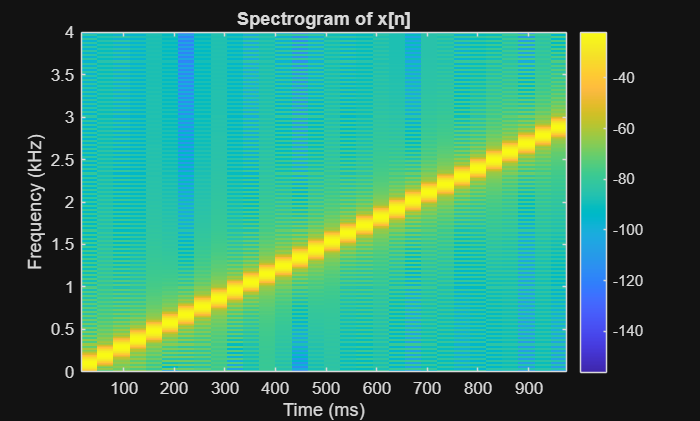

%spectogram
figure;
spectrogram(x, 512, [], 1024, fs, 'yaxis');
title('Spectrogram of x[n]');
colorbar;

## Does it agree with your understanding of the signal?

The plot matches the mathematical definition of a chirp signal perfectly. It shows that at any given moment in time, the signal is dominated by a single frequency that steadily increases. The 1024 FFT points act as an interpolator, "zooming in" on the frequency axis to make the line look smooth and continuous. The bright yellow line sweeping from 0 kHz up to 3 kHz over 1000 ms shows exactly how the frequency changes over time. It confirms that the signal is a linear frequency sweep.

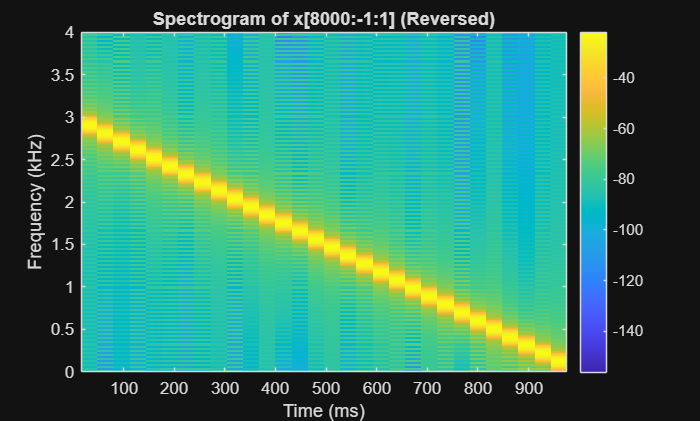

%Reversed Spectrogram
x_rev = x(8000:-1:1); % Fliping the signal samples
figure;
spectrogram(x_rev, 512, [], 1024, fs, 'yaxis');
title('Spectrogram of x[8000:-1:1] (Reversed)');
colorbar;

## Find the spectrogram of x(8000:-1:1). Does it make sense?

Notice in the second plot how the yellow trace now starts near 3 kHz at 0 ms and slopes downward to near 0 kHz at 1000 ms.the two plots of spectogram, if we put them on top of each other, they would be mirror images. This proves that time-reversing a signal in the time domain correctly maps to frequency-reversing it in the frequency domain.

The plot, generated using time-reversed samples, correctly demonstrates a downsweep from 3 kHz to 0 kHz, confirming that the spectrogram accurately tracks the signal's behavior regardless of the temporal direction.